
load('x_feat_utile_big.mat');
load('xLabelsMorph_big.mat');
%[rho, pval] = corr(x_feat_utile);
rho = cov(x_feat_utile)

rho = 1600×1600 single matrix
	1.0e+25 *

    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0009    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0

%rho(find(rho(:,:)>[0.7]))
size(rho)

ans =         1600        1600


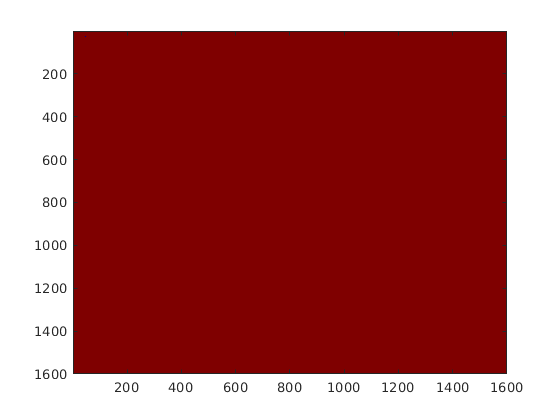


rhored = rho;

rhored(~any(~isnan(rhored), 2),:)=[];
rhored(:,~any(~isnan(rhored), 1))=[];

cuttedlabels = xLabelsMorph;

cuttedlabels(:,~any(~isnan(rho), 1))=[];



image(rhored,'CDataMapping','scaled');
colormap('jet')

% rhoreduced = rho(all(~isnan(rho(1,:)1)),:);
% rhoreduced = rhoreduced(:,all(~isnan(rho)));
% inds = find(rho(:)<[0.8]);
% inds2 = find(rho(:)>[-0.8]); 
% rho2 = rho;
% rho3 = rho;
% rho2(inds) = 0;
% rho3(inds2) = 0;
% rho2 = rho2 + rho3;




%myrowcols, myfucking = ind2sub([210, 210], find(rho(:)>[0.9]));